# HomeWork n.2 2021/22

### **PEZZOLLA LUCA 0124002411**

#### 1.  Interpolazione

Definire un dominio $[a,b]$ ed una funzione composta $f(x)$ in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale $f$sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB *ezplot *per osservarne il grafico. 

Definire quindi un insieme di $m$ punti $P=\{(x_i,y_i)\}_{i=1}^m$ con $11 \leq m \leq 21, m \in \mathbb{N}$. Le ascisse di $P$ sono linearmente distribuite in $[a,b]$, le ordinate sono i corrispondenti valori assunti dalla valutazione di $f(x)$

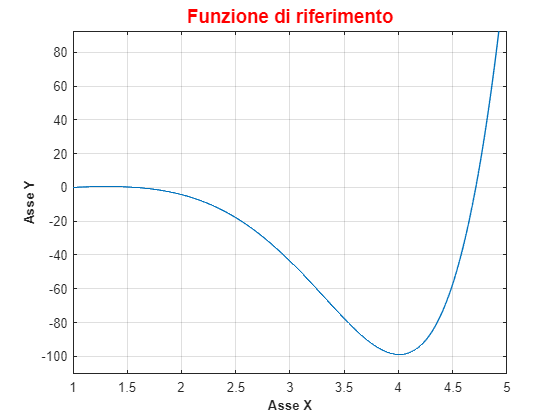

format long
funrif = @(x) exp(x).*log(x.^2).*cos(x);
a = 1;
b = 5;
dominio = [a,b];
ezplot(funrif,dominio) 
grid on 
xlabel("Asse X",FontWeight='bold',FontSize=10) 
ylabel("Asse Y",FontWeight='bold',FontSize=10)
title("Funzione di riferimento",FontWeight='bold',FontSize=14,color='r')

m = 12;
x = linspace(a,b,m);
y=funrif(x)'; 

    1.1. Definire un insieme $\mathcal{F}$di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio $p$  $\in$ $\mathcal{F}$ che interpola $f$ nei nodi $x_i$. Costruire e risolvere il relativo sistema lineare $Ba=y$ (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice $B$

insieme = @(x,j) x.^(j-1);
B = ones(m,m);
for j=1:length(x)
    B(:,j) = insieme(x,j);
end
%Risoluzione del sistema lineare Ba = y tramite function SGauss
sis = SGauss(B,y)

sis =   -6.113689166410547
  13.807654260487123
 -19.808559604715679
  24.608544088690518
 -19.864519892904731
  10.653557640801276
  -4.272930551164661
   1.190721309733772
  -0.227968069369866
   0.029231212955006


%Calcolo dell'indice di condizionamento
indice = cond(B)

indice =      7.740901647815686e+13


       1.2. Valutare il polinomio $p$ su una griglia di $N$ punti di valutazione distribuiti casualmente in $[a,b]$. Fissare $N\,\,( 201 \leq N \leq 399)$. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.

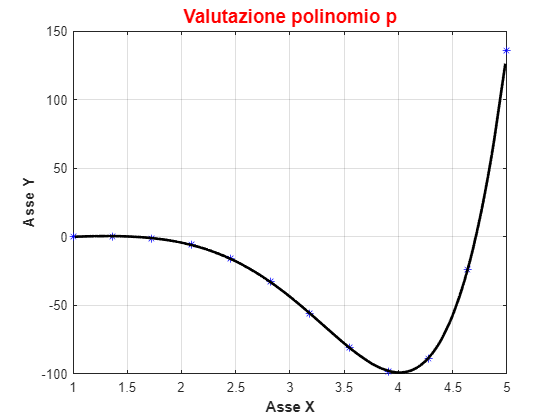

N = 222;
xx = sort(a+(b-a).*rand(N,1));
%Valutazione del polinomio p nella griglia di N punti
yy=ones(N,m);
for j = 1:m
    yy(:,j) = insieme(xx,j);
end
%Calcolo dell'errore di interpolazione
y_gamma = yy*sis;
%Visualizzazione del grafico
plot(x,y,'*',color='b')
hold on
plot(xx,y_gamma,'k',LineWidth=2)
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Valutazione polinomio p",FontWeight='bold',FontSize=14,color='r')
grid on
hold off

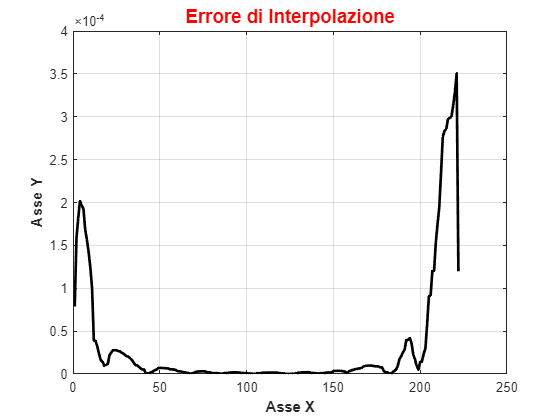

errore = abs(funrif(xx)-y_gamma);
%Visualizzazione del grafico dell'errore interpolante
plot(errore,color='k',LineWidth=2)
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Errore di Interpolazione",FontWeight='bold',FontSize=14,color='r')
grid on

 1.3. Interpolare i punti $P$ mediante una spline $s$ di terzo grado di tipo *not-a-knot*.  Valutare l'interpolante ottenuto sulla una griglia di $N$ punti di valutazione.

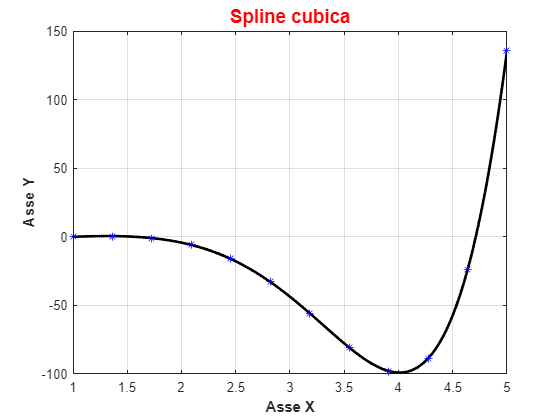

%Usiamo la function spline senza usare il terzo parametro di input
s = spline(x,y);
%Valutazione dell'interpolante ottenuto sulla griglia di N punti
xx_s = linspace(min(x),max(x),N);
%Valutazione dell'interpolante ottenuto sugli N punti di valutazione
y_s = ppval(s,xx_s);
%Visualizzazione del grafico
plot(xx_s,y_s,color='k',LineWidth=2)
hold on
plot(x,y,'*',color='b')
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Spline cubica",FontWeight='bold',FontSize=14,color='r')
grid on
hold off

        1.4. Fissare un valore $n\,\,( 10 \leq n \leq 19)$ e definire un nuovo insieme di punti $Q = \{(x_j, y_j)\}_{j=1}^n$ le cui ascisse sono i nodi di Chebyshev in $[a,b]$ e le cui ordinate sono i valori corrispondenti assunti da $f(x)$. Costruire il polinomio interpolante i punti $Q$ e valutarlo sulla griglia di valutazione generata al punto 1.2

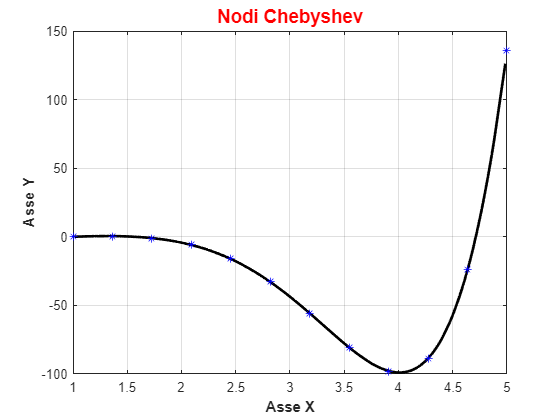

n = 12;
k = 0:n-1;
%Applichiamo la formula per calcolare i nodi di Chebyshev
xc = cos(k/(n-1)*pi);
x_cheb = (a+b)*.5-(b-a)*.5 *xc;
x_cheb = x_cheb';
%Valutazione della funzione sui nodi di Chebyshev
y_cheb = funrif(x_cheb);
%Costruzione del polinomio interpolante
for j=1:n
    B_cheb(:,j)=insieme(x_cheb,j);
end
a_cheb = SGauss(B_cheb,y_cheb);
%Valutazione nella griglia generata nel punto 1.2
yy_cheb=insieme(xx,1);
for j=2:n
    yy_cheb=[yy_cheb insieme(xx,j)];
end
yy_gamma_cheb=yy_cheb*a_cheb;
%Visualizzazione del grafico
plot(xx,yy_gamma_cheb,color='k',LineWidth=2)
hold on
plot(x,y,'*',color='b')
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Nodi Chebyshev",FontWeight='bold',FontSize=14,color='r')
grid on
hold off

 1.5. Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2.

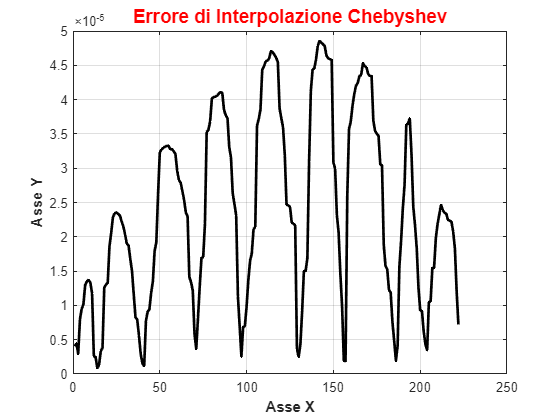

errore_cheb = abs(funrif(xx)-yy_gamma_cheb);
%Visualizzazione grafica dell'errore interpolante
plot(errore_cheb,color='k',LineWidth=2)
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Errore di Interpolazione Chebyshev",FontWeight='bold',FontSize=14,color='r')
grid on

errore 

errore = 	1.0e+-3 *

   0.078755966261668
   0.158422225159244
   0.181450989164667
   0.201744341764176
   0.196139669808471
   0.192878619190817
   0.168807221756773
   0.156535802620428
   0.142210456297420
   0.124009565361294


errore_cheb 

errore_cheb = 	1.0e+-4 *

   0.040593510903936
   0.044287700526058
   0.029630453515506
   0.079714819823384
   0.094902021567367
   0.101556598112729
   0.129351588084581
   0.135166731658476
   0.137107348678334
   0.133114108020194


1.6. Considerare il poligono di $N$vertici costituito dai valori della curva parametrica interpolata al punto (1.2) e, tramite il comando `fill, `visualizzare in una figura tale poligono colorato con un colore generato da una terna RGB.

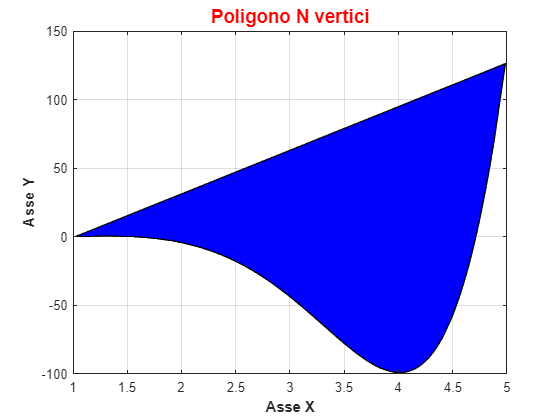

%Costruzione del poligono
for i = 1:N
    y_p(:,i) = y_gamma(i);
end
for i = 1:N
    x_p(:,i) = xx(i);
end
%Utilizziamo il comando fill per colorare il poligono
fill(x_p,y_p,'b')
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Poligono N vertici",FontWeight='bold',FontSize=14,color='r')
grid on

 2.** Interpolazione di curve parametriche**

  Si considerino le seguenti curve parametriche:

         1. $x = 4\sin\Big(\frac{1}{4}t\Big)\quad\quad y = 1 - 2\cos^2\Big(\frac{1}{4}t\Big)\quad\quad -52\pi \leq t \leq 34\pi$

         2. $x = 2e^t\quad\quad y = \cos(1+e^{3t})\quad\quad  0 \leq t \leq \frac{3}{4}$

         3. $x = t\cos(t)\quad\quad y = t\sin(t)\quad\quad -2\pi \leq t \leq 2\pi$

         4. $x = \cos t
 + \frac{1}{4}\cos(8t)\quad\quad y = \sin t + \frac{1}{4}\sin(8t)\quad\quad 0\leq t \leq 2\pi$

Scegliere una di tali curve e campionarla in $n$ punti $P=\{(x_i,y_i)\}_{i=1}^n$, corrispondenti a $n$ punti $t_i$ equispaziati nell'intervallo $[a,b]$ in cui varia il parametro $t$ (fissare $20<n<30$).

Scelgo la curva del punto numero 3.

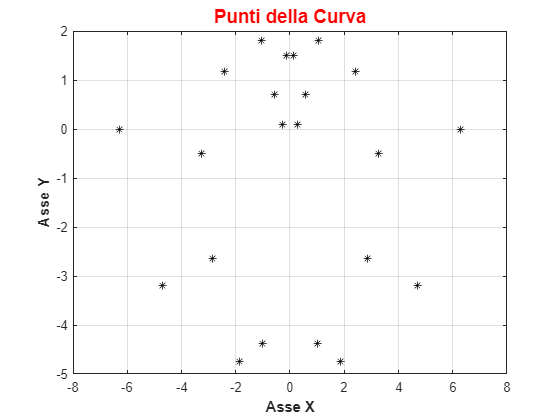

%Definiamo la curva parametrica del terzo punto
xt = @(t) t.*cos(t);
yt = @(t) t.*sin(t);
n_c = 22;
%L'intervallo [a,b] è il seguente:
a_c = -1;
b_c = 5;
dominio_c = [a_c,b_c];
t = linspace(-2*pi,2*pi,n_c);
x_c = xt(t);
y_c = yt(t);
%Visualizzazione del grafico
plot(x_c,y_c,'*',color='k')
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Punti della Curva",FontWeight='bold',FontSize=14,color='r')
grid on

 2.1. costruire due spline parametriche $p_x$ e $p_y$ che interpolino rispettivamente i punti $(t_i,x_i)$ e i punti $(t_i, y_i)$  ($i = 1,\ldots, n$);

xx_c = linspace(-2*pi,2*pi,500);
%Costruzione delle spline parametriche
xs_c=spline(t,x_c,xx_c);
ys_c=spline(t,y_c,xx_c);

  2.2.  valutare le spline parametriche su una griglia fitta opportuna e mostrare il grafico della curva parametrica interpolata.

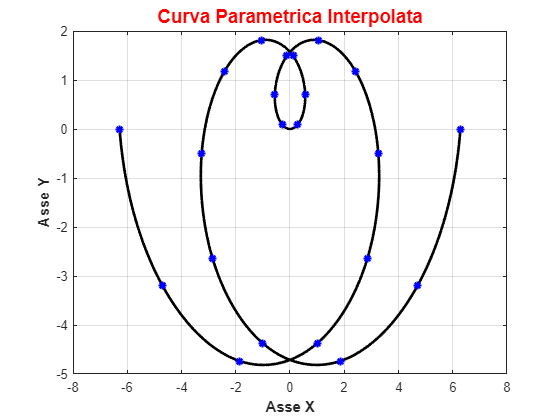

%Visualizzazione grafica della curva parametrica interpolata
plot(xs_c,ys_c,color='k',LineWidth=2)
hold on
plot(x_c,y_c,'*',color='b',LineWidth=1.5)
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Curva Parametrica Interpolata",FontWeight='bold',FontSize=14,color='r')
grid on
hold off

   2.3.  Ripetere i punti (2.1) e (2.2) su un insieme di $m=40$ punti $S = \{(x_j,y_j)\}_{j=1}^m$ le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando `ginput` usato su una immagine a propria scelta oppurtunamente caricata (usare `imread). `Le coordinate devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che `x` e `y` siano i vettori delle coordinate dei vertici di un poligono (chiuso). 

nuvola = imread("nuvola.jpg");
image(nuvola)
load("variabili.mat")

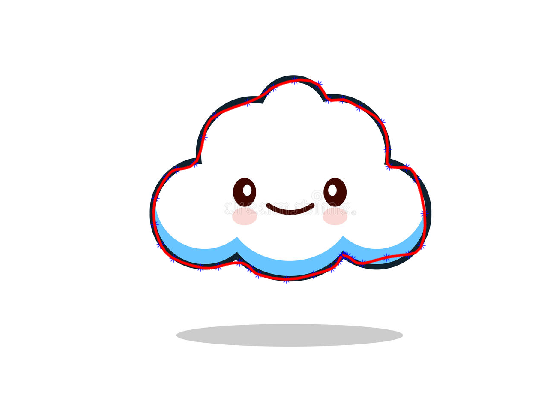

%Uniamo i punti in modo tale da avere un poligono chiuso
x_nuvola(end+1) = y_nuvola(1);
y_nuvola(end+1) = x_nuvola(1);
%Ripetiamo i punti 2.1 e 2.2
t_nuvola = 1:length(x_nuvola);
t_nuvola = t_nuvola';
xx_nuvola = linspace(t_nuvola(1),t_nuvola(end));
xs_nuvola = spline(t_nuvola,x_nuvola,xx_nuvola);
ys_nuvola = spline(t_nuvola,y_nuvola,xx_nuvola);
hold on
%Visualizzazione dell'immagine
imshow(nuvola)
%Visualizzazione del grafico
plot(x_nuvola,y_nuvola,'*',color='b');
plot(xs_nuvola,ys_nuvola,color='r',LineWidth=2)
hold off

   2.4. Calcolare il perimetro del poligono ottenuto al punto precedente tramite un'opportuna function che sarà allegata in fondo al file .mlx

%Calcoliamo il perimetro del poligono tramite apposita function 
perimetro_nuvola = Perimetro(x_nuvola,y_nuvola,40)

perimetro_nuvola =      1.260829493087558e+03


 2.5. Ricostruire inoltre la curva parametrica passante per i punti definiti al punto (2.3) mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite.  

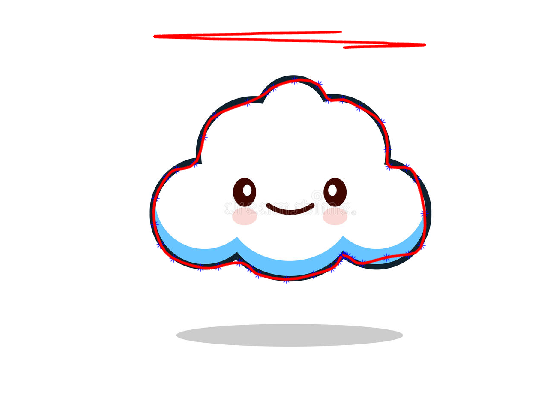

hold on
%Utilizziamo il comando pchip per la cubica di Hermite
xh = pchip(t_nuvola,x_nuvola,xx_nuvola);
yh = pchip(t_nuvola,t_nuvola,xx_nuvola);
%Visualizzazione del risultato
plot(xh,yh,color='r',LineWidth=2)
hold off

%Calcolo della norma infinito delle ordinate
norma_infinito = norm(y_nuvola,inf)

norma_infinito =      5.800918367346939e+02


3. **Approssimazione**

Scaricare il dataset dell'andamento del covid da [https://github.com/pcm-dpc/COVID-19](https://github.com/pcm-dpc/COVID-19)

Caricare il dataset in matlab utilizzando il comando `readtable`.

Generare un insieme di punti $C=\{(t_i,y_i)\}_{i=1}^n$ le cui ascisse il tempo $t_1,t_2,\ldots,t_n$. I valori sono estratti dalla tabella precedentemente caricata. Scegliere una colonna a piacere che descrive un attributo della tabella. Scegliere inoltre $5 \leq n \leq 11$.

dataset=readtable("dpc-covid19-ita-andamento-nazionale.csv");
%Selezioniamo la colonna che indica il numero di ricoverati con sintomi
n = 8;
%Insieme di punti C
Cx = 1:n;
Cy = dataset.ricoverati_con_sintomi(Cx);

3.1 Costruire e valutare, su una griglia fitta di almeno 100 punti, utilizzando i metodi studiati, la retta dei minimi quadrati approssimante i dati.

%Matrice B per risolvere il sistema lineare B*a = y
B = [ones(n, 1), Cx'];
a = Sgauss_pivot(B'*B, B'*Cy);
dim = 239; 
griglia = linspace(min(Cx), max(Cx), dim); 
% Costruzione matrice B2 utilizzando la griglia creata in precedenza
B2 = [ones(dim, 1), griglia']; 
y = B2*a

y = 	1.0e+02 *

   0.052499999999998
   0.080609243697477
   0.108718487394956
   0.136827731092435
   0.164936974789914
   0.193046218487393
   0.221155462184872
   0.249264705882351
   0.277373949579830
   0.305483193277309


  3.2. Mostrare graficamente sia il polinomio di primo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti.

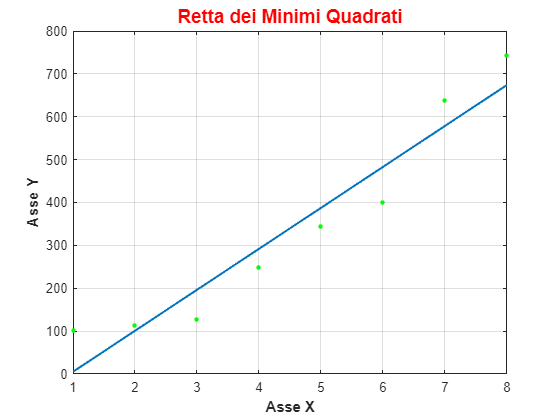

%Visualizzazione grafico
plot(griglia, y, "LineWidth", 1.5);
hold on
plot(Cx,Cy,".","MarkerSize", 10,"Color","green") 
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Retta dei Minimi Quadrati",FontWeight='bold',FontSize=14,color='r')
grid on;
hold off;

3.3. Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 2 e 10. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.

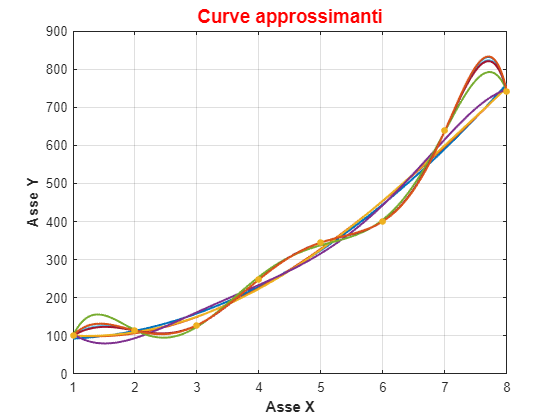

Y = zeros(dim,8);
proj_Y = zeros(n, 8);
for i=2:10
    B1i = ones(n, i+1); 
    B2i = ones(dim, i+1);
    for j=1:i
        B1i(:, j+1) = (Cx.^j)'; 
        B2i(:, j+1) = (griglia.^j)';
    end
    ai = SGauss(B1i'*B1i, B1i'*Cy); 
    Y(:, i-1) = B2i*ai; 
    %Calcoliamo le proiezioni dei punti sul polinomio che useremo per calcolare i residui.
    proj_Y(:, i-1) = B1i*ai; 
    plot(griglia, Y(:, i-1), "LineWidth", 1.5); 
    hold on;
end
plot(Cx, Cy, ".", "MarkerSize", 15);
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Curve approssimanti",FontWeight='bold',FontSize=14,color='r')
grid on;
hold off;

3.4. Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute.

%Matrice dei residui
residui = zeros(n, 9);
for i=1:n
    for j=1:9
        %Calcoliamo il residuo in norma-2 del j-esimo polinomio
        residui(i, j) = norm(abs(proj_Y(i, j)-Cy(i)), 2); 
    end
end
residui 

residui =    8.166666666666686   0.848484848484944   0.719696969696656   4.062354312310731   0.202797215891593   0.000000031781639   0.000000009853153   0.000000001126836   0.000000001024489
   0.666666666666686   7.106060606060510   4.193722943723287  19.906177156056003   1.419580485447341   0.000000217715353   0.000000076737891   0.000000005880665   0.000000004838824
  30.857142857142833  21.841991341991417  22.514069264069235  34.127622377552655   4.258741378094783   0.000000633328114   0.000000241670364   0.000000012882708   0.000000009002463
  18.595238095238102  22.458874458874362  24.475108225107874  14.227855477937624   7.097902164136030   0.000001014022018   0.000000404016362   0.000000015465588   0.000000008305790
  20.023809523809518  16.160173160173088  18.176406926406571  28.423659673610473   7.097902031267949   0.000000966201696   0.000000391809635   0.000000011035581   0.000000003624052
  44.571428571428555  53.586580086580227  54.258658008657960  42.645104895182158   4.

4.1. Definire un dominio $[a,b]$ ed una funzione composta $f(x)$ in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc etc). La funzione deve essere definita, positiva e continua in $[a,b]$. Usare la funzione `ezplot` per stabilire l'intervallo $[a,b]$; 

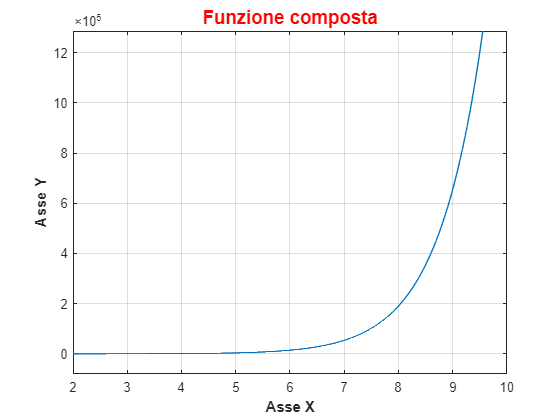

f = @(x) x.^2.*exp(x);
a = 2;
b = 10;
ezplot(f, [a, b]) 
ylabel("Asse Y",FontWeight='bold',FontSize=11)
xlabel("Asse X",FontWeight='bold',FontSize=11)
title("Funzione composta",FontWeight='bold',FontSize=14,color='r')
grid on;
hold off;

4.2. Considerare come valore esatto dell'integrale $I=I[f]=\int_a^b f(x)dx$ il valore ottenuto mediante la funzione MATLAB `integral` con tolleranza $10^{-9}$;

% Calcolo dell'integrale definito con apposita funzione MATLAB
area = integral(f, a, b, "AbsTol", 1e-9) 

area =      1.806155417061953e+06


    4.3. Stimare l'integrale $I$ utilizzando le principali formule di quadratura (Rect. sx, Rect. dx, Punto medio, Trapez., Simpson) su $1, 2,$ e $3$ nodi e calcolare per ognuna di esse il corrispondente errore di discretizzazione. 

%Applichiamo la formula rettangolare sinistra per calcolare l'area
retta_sx_area = (b-a)*f(a)

retta_sx_area =      2.364497951657808e+02


%Applichiamo la formula rettangolare destra per calcolare l'area
retta_dx_area = (b-a)*f(b)

retta_dx_area =      1.762117263584537e+07


%Applichiamo la formula del punto medio per calcolare l'area
punti_medi_area = (b-a)*f((b+a)/2)

punti_medi_area =      1.161874925259077e+05


%Applichiamo la formula trapezoidale per calcolare l'area
trapezoidale_area = (b-a)/2*f(a)+(b-a)/2*f(b)

trapezoidale_area =      8.810704542820269e+06


%Applichiamo la formula di Simpson per calcolare l'area
simpson_area = (b-a)/6*f(a)+4*(b-a)/6*f((a+b)/2)+(b-a)/6*f(b)

simpson_area =      3.014359842624029e+06


%Errore discretizzazione formula rettangolare sinistra
err_rett_sx = abs(retta_sx_area)

err_rett_sx =      2.364497951657808e+02


%Errore discretizzazione formula rettangolare destra
err_rett_dx = abs(retta_dx_area)

err_rett_dx =      1.762117263584537e+07


%Errore discretizzazione formula punto medio
err_punti_medi = abs(punti_medi_area)

err_punti_medi =      1.161874925259077e+05


%Errore discretizzazione formula trapezoidale
err_trapezoidale = abs(trapezoidale_area)

err_trapezoidale =      8.810704542820269e+06


%Errore discretizzazione formula di Simpson
err_simpson = abs(simpson_area)

err_simpson =      3.014359842624029e+06


    4.4. **Costruzione di formule di quadratura. **Fissare $p$ $3 \leq p \leq 5$ nodi distinti, **non** **equispaziati**, $x_i \in [0,4]$  di una formula di quadratura 

                                                                                   
$$Q[f]=w_1f(x_1)+w_2f(x_2)+\cdots+w_pf(x_p)$$
                            

    per il calcolo numerico dell'integrale definito della funzione $f$ in $[0,4]$;

p = 4;
xi =[0.2 1.2 2.5 3.9];

  4.5.  Determinare i valori dei pesi $w_i$ affinché la formula risulti esatta per polinomi algebrici di grado al più $p-1$ (costruire e risolvere il sistema $B^Tw=I$.)

%Inizializzazione delle matrici dei termini noti
I = zeros(p, 1);
B = zeros(p, p);

%Costruzione matrici
for i=1:p
    I(i, 1) = (xi(p)^i-xi(1)^i)/i;
    B(i, :) = xi.^(i-1);
end
w = B'\I 

w =    2.812612491373359
   4.802160397975626
  -2.053808661145627
   1.138471934667589


function dist = Perimetro(x,y,m)
dist = 0;
punto = [x y];
for i = 1:m-1
    dist = dist + norm(punto(i) - punto(i+1));
end
dist = dist + norm(punto(1) - punto(m));
end